clear all
clc
real_value = 72;
N = 1000   % datasize

N = 1000

w = sqrt(1/2).*randn(1,N);
x = real_value * ones(1,N);
data = x + w

data =    70.8764   70.5820   73.4346   72.8015   72.5396   72.3721   71.3073   72.0969   71.8115   72.3218   71.6001   73.7477   71.1191   72.5542   72.4649   71.8012   74.1647   71.6913   71.9091   73.5453   73.1981   70.9465   72.7892   72.3008   72.3840   71.6046   71.0680   71.0327   71.1689   71.5710   71.1658   72.7127   72.1745   72.1589   71.1384   72.5159   70.2244   71.5452   72.4211   73.4158   71.7068   72.6142   73.5886   71.5578   71.5038   73.6363   72.0834   72.8066   72.2177   72.5300


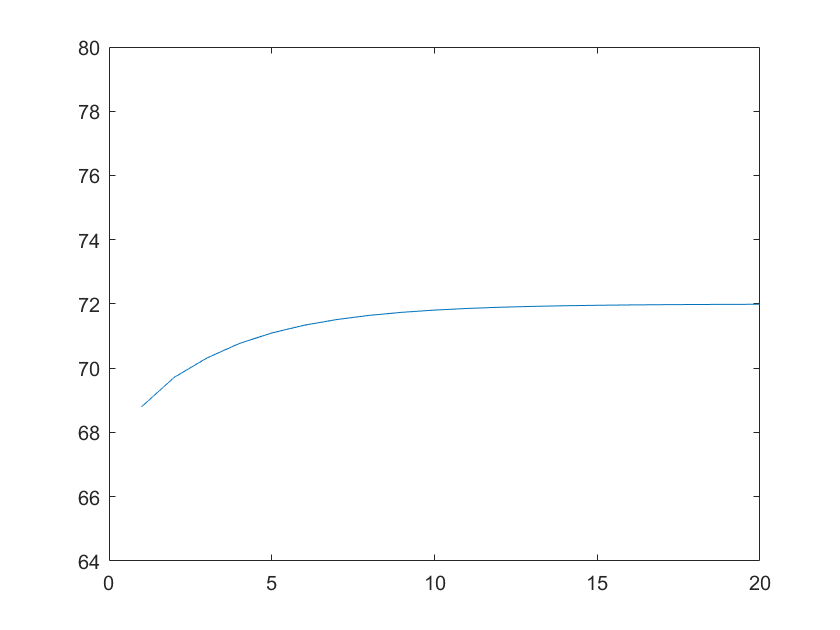

EST_prev = 68;
E_est_prev = 2;
E_est = 1;
MEA = 75;
E_mea = 4;
i = 1;
y_axis = zeros(1,10);
EST_array = zeros(1,10);
EST = 8;
tolerance = 0.01;



while EST <= (real_value - tolerance) || EST >= (real_value + tolerance)
    
MEA = x(i);

KG = E_est / (E_est + E_mea);

EST = EST_prev + KG * (MEA - EST_prev);

E_est = (1-KG)*(E_est_prev);

EST_prev = EST;
EST_array(i) = EST;
y_axis(i) = i;
i = i+1;

end

plot(y_axis, EST_array)
ylim([64 80])